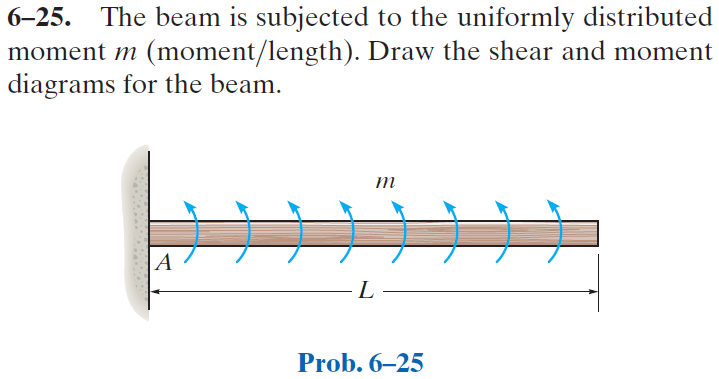

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-25P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-25P-solution-9780136022305) 

[https://www.youtube.com/watch?v=nfSwg17swVQ](https://www.youtube.com/watch?v=nfSwg17swVQ) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# distributed moment data

M = sym('M');
L = sym('L');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'moment', 'Ma', 0);
b = b.add('distributed', 'moment', M, [0 L]);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \frac{M\,x^{2}\,\left(3\,L-x\right)}{6\,\text{E}\,\text{I}}$$

dy

$$dy(x) = \frac{M\,x\,\left(2\,L-x\right)}{2\,\text{E}\,\text{I}}$$

m

$$m(x) = M\,\left(L-x\right)$$

v

$$v(x) = 0$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ma} & -L\,M\\ \mathrm{Ra} & 0 \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and bending moment diagram

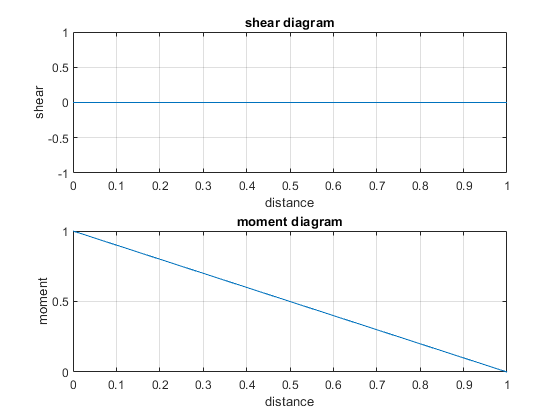

beam.shear_moment(m, v, [0 1], [M L], 1);

# clean up

addvar(y);
assume(old_assum);
clear old_assum;